# 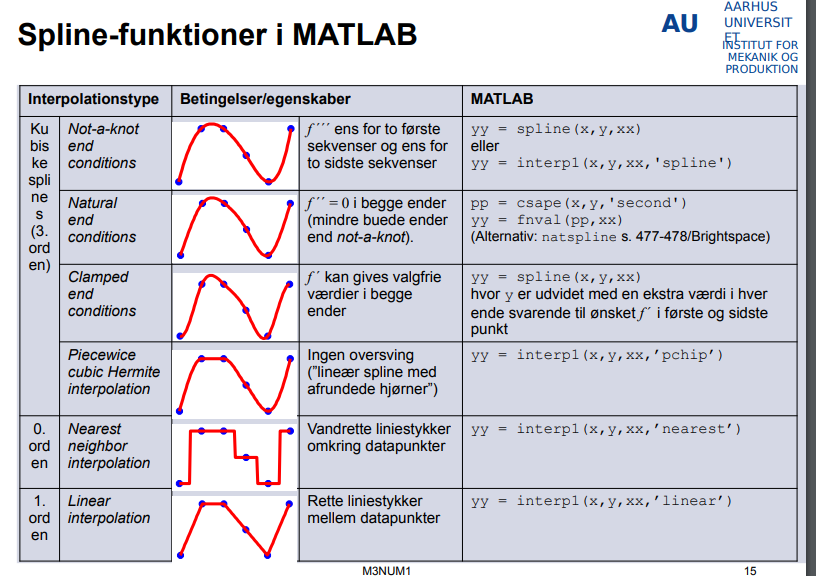

# Interpolation m. plots

Hvis der er givet noget data, er der herunder forskellige måder at illustrere det på

## Polynomiefit

clear

% Data til analyse
% Afhængig variabel
lgd = [10.8086 10.9961 11.1300 11.2429 11.7808 12.1242 12.2231 12.2897 12.5993 12.7380 14.1194 14.7380]; % Længdegrad øst (decimalgrader) 
% Uafhængig variabel
brd = [54.6616 54.5881 54.5794 54.5541 54.3979 54.4002 54.4525 54.5797 54.7128 54.7489 55.0114 55.3174]; % Breddegrad nord (decimalgrader)

format short

% Polyfit
n = length(lgd)

n = 12


koeff = polyfit(lgd, brd, n-1)';


% Tabbel over værdier
T = table(koeff, lgd', brd', 'VariableNames',{'Koeff', 'Længdegrader', 'Breddegrader'});
disp(T)

       Koeff       Længdegrader    Breddegrader
    ___________    ____________    ____________

        -18.459       10.809          54.662   
           2499       10.996          54.588   
    -1.5363e+05        11.13          54.579   
     5.6619e+06       11.243          54.554   
    -1.3898e+08       11.781          54.398   
     2.3858e+09       12.124            54.4   
    -2.9229e+10       12.223          54.453   
     2.5556e+11        12.29           54.58   
    -1.5627e+12       12.599          54.713   
     6.3649e+12       12.738          54.749   
    -1.5542e+13       14.119          55.011   
     1.7235e+13       14.738          55.317   



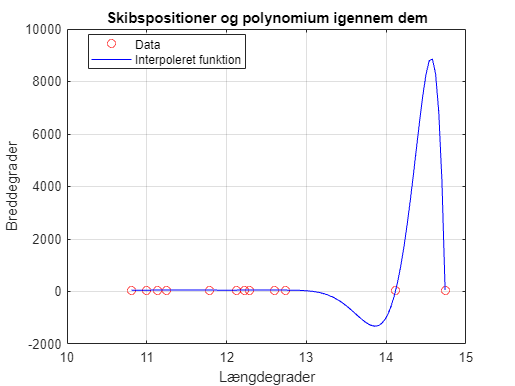


% der plottes for at se hvor godt fittet er

lgdlin = linspace(min(lgd), max(lgd));
brds = polyval(koeff, lgdlin);

plot(lgd, brd, 'ro', 'DisplayName', 'Data'), grid("on"), title('Skibspositioner og polynomium igennem dem')
xlabel('Længdegrader'), ylabel('Breddegrader')
hold on
plot(lgdlin, brds,'b', 'DisplayName','Interpoleret funktion')

legend('Location','best')
hold off



bump_475mm = polyval(koeff, 4.75)

bump_475mm = 7.4425e+10

## Lineært fit

clear
% Data
% Afhængig variabel
lgd = [10.8086 10.9961 11.1300 11.2429 11.7808 12.1242 12.2231 12.2897 12.5993 12.7380 14.1194 14.7380]; % Længdegrad øst (decimalgrader) 
% Uafhængig variabel
brd = [54.6616 54.5881 54.5794 54.5541 54.3979 54.4002 54.4525 54.5797 54.7128 54.7489 55.0114 55.3174]; % Breddegrad nord (decimalgrader)

% Data til plot
lgdlin = linspace(min(lgd), max(lgd))

lgd1 =    10.8086   10.8483   10.8880   10.9277   10.9674   11.0071   11.0467   11.0864   11.1261   11.1658   11.2055   11.2452   11.2849   11.3246   11.3643   11.4040   11.4437   11.4833   11.5230   11.5627   11.6024   11.6421   11.6818   11.7215   11.7612   11.8009   11.8406   11.8803   11.9199   11.9596   11.9993   12.0390   12.0787   12.1184   12.1581   12.1978   12.2375   12.2772   12.3169   12.3565   12.3962   12.4359   12.4756   12.5153   12.5550   12.5947   12.6344   12.6741   12.7138   12.7535


% Interpolering mellem de 2 datasæt
brd_kub = interp1(lgd, brd, lgdlin, 'linear') 

brd1 =    54.6616   54.6460   54.6305   54.6149   54.5994   54.5874   54.5848   54.5822   54.5797   54.5714   54.5625   54.5534   54.5419   54.5304   54.5189   54.5073   54.4958   54.4843   54.4728   54.4612   54.4497   54.4382   54.4266   54.4151   54.4036   54.3980   54.3983   54.3986   54.3988   54.3991   54.3994   54.3996   54.3999   54.4002   54.4181   54.4391   54.4800   54.5558   54.5914   54.6084   54.6255   54.6426   54.6596   54.6767   54.6938   54.7108   54.7219   54.7323   54.7426   54.7518


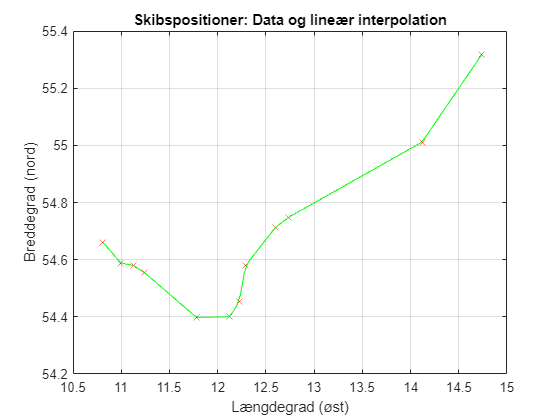


% Plot
plot(lgd,brd,"rx", lgdlin, brd_kub,'g')
title('Skibspositioner: Data og lineær interpolation')
xlabel('Længdegrad (øst)')
ylabel('Breddegrad (nord)')
grid()


% Find specifik værdi
breddegrad_ved_12_4_ost = interp1(lgd,brd,12.4,'Linear')

breddegrad_ved_12_4_ost = 54.6271

## Not a knot

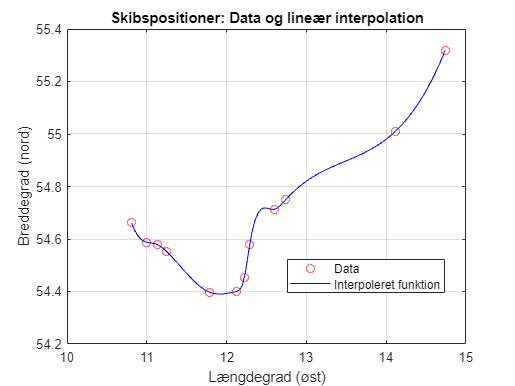

clear
% Data
% Afhængig variabel
lgd = [10.8086 10.9961 11.1300 11.2429 11.7808 12.1242 12.2231 12.2897 12.5993 12.7380 14.1194 14.7380]; % Længdegrad øst (decimalgrader) 
% Uafhængig variabel
brd = [54.6616 54.5881 54.5794 54.5541 54.3979 54.4002 54.4525 54.5797 54.7128 54.7489 55.0114 55.3174]; % Breddegrad nord (decimalgrader)

% Linspace til plot
lgdlin = linspace(min(lgd), max(lgd));

% Not a knot spline oprettes
spl_func = spline(lgd,brd,lgdlin);

% Data plottes
plot(lgd,brd, 'ro', 'DisplayName', 'Data'), grid("on")
title('Skibspositioner: Data og lineær interpolation')
xlabel('Længdegrad (øst)')
ylabel('Breddegrad (nord)')

hold on

% Fit plottes
plot(lgdlin, spl_func,'b', 'DisplayName','Interpoleret funktion')

legend('Location','best')
hold off


% Find specifik værdi
breddegrad_ved_12_4_ost = spline(lgd,brd,12.4)

breddegrad_ved_12_4_ost = 54.7020

## Kubisk plot

clear
% Data
% Afhængig variabel
lgd = [10.8086 10.9961 11.1300 11.2429 11.7808 12.1242 12.2231 12.2897 12.5993 12.7380 14.1194 14.7380]; % Længdegrad øst (decimalgrader) 
% Uafhængig variabel
brd = [54.6616 54.5881 54.5794 54.5541 54.3979 54.4002 54.4525 54.5797 54.7128 54.7489 55.0114 55.3174]; % Breddegrad nord (decimalgrader)

% Linspace
lgdlin = linspace(min(lgd), max(lgd))

lgdlin =    10.8086   10.8483   10.8880   10.9277   10.9674   11.0071   11.0467   11.0864   11.1261   11.1658   11.2055   11.2452   11.2849   11.3246   11.3643   11.4040   11.4437   11.4833   11.5230   11.5627   11.6024   11.6421   11.6818   11.7215   11.7612   11.8009   11.8406   11.8803   11.9199   11.9596   11.9993   12.0390   12.0787   12.1184   12.1581   12.1978   12.2375   12.2772   12.3169   12.3565   12.3962   12.4359   12.4756   12.5153   12.5550   12.5947   12.6344   12.6741   12.7138   12.7535



% Kubisk fit
brd_kub = interp1(lgd, brd, lgdlin, 'PCHIP') 

brd_kub =    54.6616   54.6394   54.6199   54.6040   54.5928   54.5870   54.5844   54.5826   54.5798   54.5736   54.5639   54.5535   54.5426   54.5299   54.5159   54.5010   54.4857   54.4703   54.4553   54.4412   54.4283   54.4172   54.4082   54.4017   54.3983   54.3979   54.3979   54.3980   54.3982   54.3984   54.3987   54.3991   54.3995   54.4001   54.4081   54.4320   54.4733   54.5628   54.6003   54.6255   54.6458   54.6624   54.6761   54.6882   54.6996   54.7114   54.7232   54.7337   54.7433   54.7524


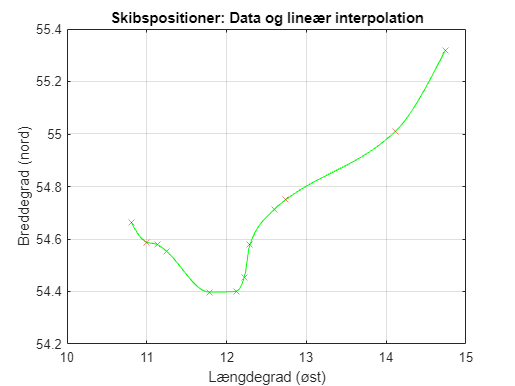


plot(lgd,brd,"rx", lgdlin, brd_kub,'g')
title('Skibspositioner: Data og lineær interpolation')
xlabel('Længdegrad (øst)')
ylabel('Breddegrad (nord)')
grid


% Find specifik værdi
breddegrad_ved_12_4_ost = interp1(lgd,brd,12.4,'PCHIP')

breddegrad_ved_12_4_ost = 54.6475

## Nearest

clear
% Data
% Afhængig variabel
lgd = [10.8086 10.9961 11.1300 11.2429 11.7808 12.1242 12.2231 12.2897 12.5993 12.7380 14.1194 14.7380]; % Længdegrad øst (decimalgrader) 
% Uafhængig variabel
brd = [54.6616 54.5881 54.5794 54.5541 54.3979 54.4002 54.4525 54.5797 54.7128 54.7489 55.0114 55.3174]; % Breddegrad nord (decimalgrader)

% Data til plot
lgdlin = linspace(min(lgd), max(lgd))

lgdlin =    10.8086   10.8483   10.8880   10.9277   10.9674   11.0071   11.0467   11.0864   11.1261   11.1658   11.2055   11.2452   11.2849   11.3246   11.3643   11.4040   11.4437   11.4833   11.5230   11.5627   11.6024   11.6421   11.6818   11.7215   11.7612   11.8009   11.8406   11.8803   11.9199   11.9596   11.9993   12.0390   12.0787   12.1184   12.1581   12.1978   12.2375   12.2772   12.3169   12.3565   12.3962   12.4359   12.4756   12.5153   12.5550   12.5947   12.6344   12.6741   12.7138   12.7535


% Interpolering mellem de 2 datasæt
brd_kub = interp1(lgd, brd, lgdlin, "nearest") 

brd_kub =    54.6616   54.6616   54.6616   54.5881   54.5881   54.5881   54.5881   54.5794   54.5794   54.5794   54.5541   54.5541   54.5541   54.5541   54.5541   54.5541   54.5541   54.5541   54.3979   54.3979   54.3979   54.3979   54.3979   54.3979   54.3979   54.3979   54.3979   54.3979   54.3979   54.4002   54.4002   54.4002   54.4002   54.4002   54.4002   54.4525   54.4525   54.5797   54.5797   54.5797   54.5797   54.5797   54.7128   54.7128   54.7128   54.7128   54.7128   54.7489   54.7489   54.7489


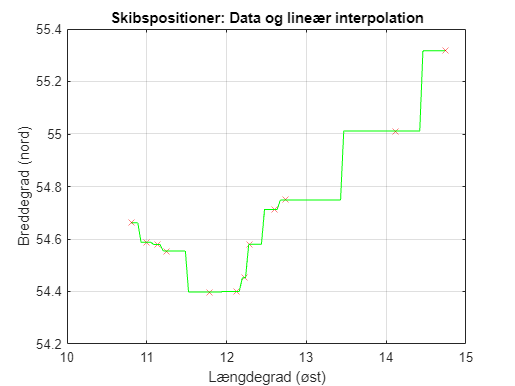


% Plot
plot(lgd,brd,"rx", lgdlin, brd_kub,'g')
title('Skibspositioner: Data og lineær interpolation')
xlabel('Længdegrad (øst)')
ylabel('Breddegrad (nord)')
grid()


% Find specifik værdi
breddegrad_ved_12_4_ost = interp1(lgd,brd,12.4,'Linear')

breddegrad_ved_12_4_ost = 54.6271